clear; close all; clc
load('cam1_1.mat')
load('cam1_2.mat')
load('cam1_3.mat')
load('cam1_4.mat')
load('cam2_1.mat')
load('cam2_2.mat')
load('cam2_3.mat')
load('cam2_4.mat')
load('cam3_1.mat')
load('cam3_2.mat')
load('cam3_3.mat')
load('cam3_4.mat')


clear; close all; clc
load('cam1_1.mat')
numFrames1_1 = size(vidFrames1_1, 4);
%Y = uint8(zeros(480, 640, 226));
X = zeros( 480 * 640, 226);

for j = 1:numFrames1_1
    i = vidFrames1_1(:,:,:,j);
    gray = rgb2gray(i);
    downgray = imresize(gray,1/4);
    X(:, j) = reshape(gray,[1, 480 * 640]);
end

for i = 1:480*640
    X(i, :) = X(i, :) - mean(X(i, :));
end



width = 70;
height = 80;
figure(1)
R = zeros(height * width, numFrames1_1);
P1 = zeros(2, numFrames1_1);
for j = 1:numFrames1_1
    image = reshape(X(:,j),[480, 640]);

    kernel = ones(height, width);
    pimage = abs(image);
    output = conv2(kernel, pimage);
    maxval = max(output(:));
    [y, x] = find(output == maxval);
    y = y - height;
    x = x - width; 
    P1(:, j) = [y, x];
    object = image(y:y+height-1,x:x+width-1);
    R(:, j) = reshape(object, [width * height, 1]);
    [u1,s1,v1] = svd(object, 'econ');
    lambda = diag(s1);
    
    subplot(2,2,1) 
    imagesc(image);
    axis equal
    hold on
    rectangle('Position',[x,y,width, height],'Edgecolor', 'r');
    hold off
    drawnow
    subplot(2,2,2)
    i = vidFrames1_1(:,:,:,j);
    imshow(i);
    hold on
    rectangle('Position',[x,y,width, height],'Edgecolor', 'r');
    hold off
    drawnow
    subplot(2,2,3);
    from = 0;
    end1 = 200;
    edges = linspace(0, end1, 21); % Create 20 bins.
    % Plot the histogram.
    histogram(lambda, 'BinEdges',edges); axis([from end1 0 20])
    % Fancy up the graph.
    grid on;
    xlim([from, end1]);
    xlabel('eigenvalue', 'FontSize', 14);
    ylabel('count', 'FontSize', 14);
    title('Histogram of eigenvalues', 'FontSize', 14);
    subplot(2,2,4) 
    imagesc(object);
    axis equal
end

figure(2)
from = 20;
end1 = 50;
edges = linspace(0, end1, 51)
[U,S,V] = svd(R, 'econ');
lambda = diag(S);
Y = U' * R;
histogram(lambda, 'BinEdges',edges); axis([from end1 0 8])
grid on;
xlim([from, end1]);
xlabel('eigenvalue', 'FontSize', 14);
ylabel('count', 'FontSize', 14);
title('Histogram of eigenvalues', 'FontSize', 14);


[d1_1, X1_1] = findpath(vidFrames1_3, 0);
[d2_1, X2_1] = findpath(vidFrames2_3, 0);
[d3_1, X3_1] = findpath(vidFrames3_3, 0);


[d3_1, X3_1] = findpath(vidFrames3_3, 0);

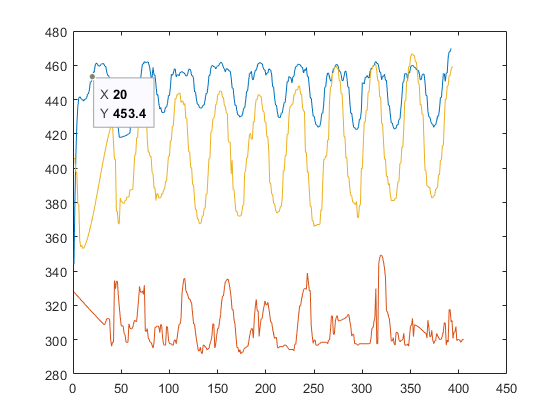

figure(5)
plot(1:length(d1_1), d1_1, 1:length(d2_1), d2_1, 1:length(d3_1), d3_1); 

[d1_1, X1_1] = findpath(vidFrames1_3, 0);
[d2_1, X2_1] = findpath(vidFrames2_3, 0);
[d3_1, X3_1] = findpath(vidFrames3_3, 0);
[u1,s1,v1] = svd(X1_1, 'econ');
[u2,s2,v2] = svd(X2_1, 'econ');
[u3,s3,v3] = svd(X3_1, 'econ');

[d1_1, X1_1] = findpath(vidFrames1_4, 0);
[d2_1, X2_1] = findpath(vidFrames2_4, 0);
[d3_1, X3_1] = findpath(vidFrames3_4, 0);
[u1,s1,v1] = svd(X1_1, 'econ');
[u2,s2,v2] = svd(X2_1, 'econ');
[u3,s3,v3] = svd(X3_1, 'econ');
from = 0;
end1 = 10000;
lambda = [diag(s1);diag(s2);diag(s3)];
figure(6)
edges = linspace(0, end1, 51)

edges =            0         200         400         600         800        1000        1200        1400        1600        1800        2000        2200        2400        2600        2800        3000        3200        3400        3600        3800        4000        4200        4400        4600        4800        5000        5200        5400        5600        5800        6000        6200        6400        6600        6800        7000        7200        7400        7600        7800        8000        8200        8400        8600        8800        9000        9200        9400        9600        9800


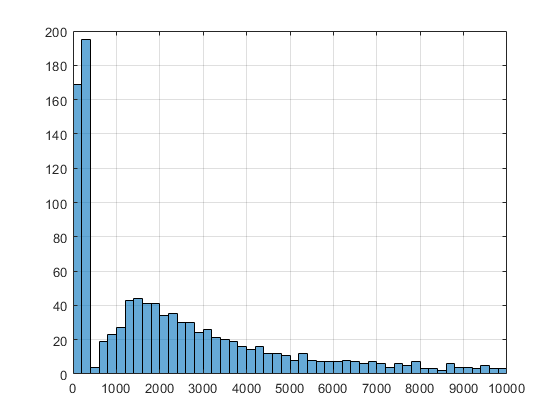

histogram(lambda, 'BinEdges',edges); axis([from end1 0 200])
grid on;
xlim([from, end1]);